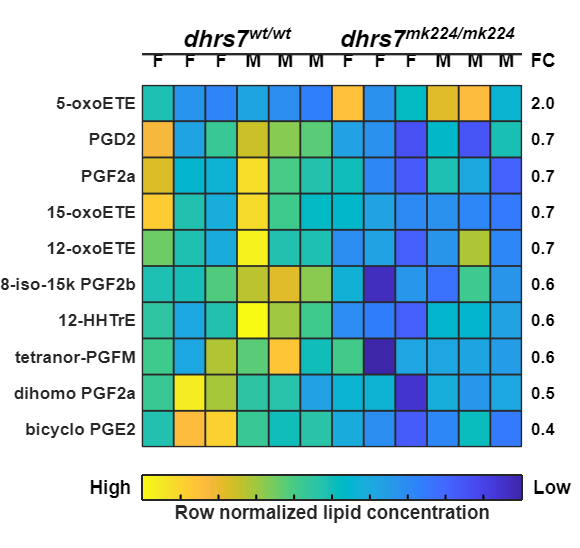

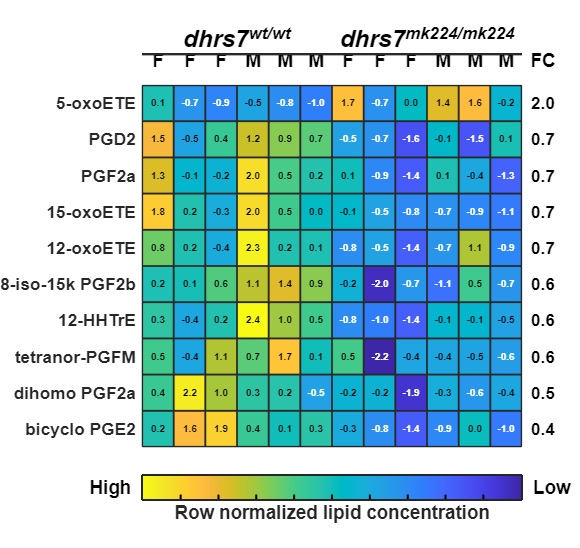

% Load the dataset
sheet = 'LipidMapsSD data';
[package_folder, filename, data_sheet_index, metadata_sheet_index] = ...
    locate_analysis_package(sheet);
output_folder = fullfile(package_folder, 'Outputs');
if ~isfolder(output_folder)
    mkdir(output_folder);
end
swtest_function = resolve_local_swtest(package_folder);
raw_data = readcell(filename, 'Sheet', data_sheet_index);
if size(raw_data, 1) < 2 || size(raw_data, 2) < 13
    error('LipidMapsSD data must contain a header row, lipid names, and 12 sample columns.');
end

% Read and validate sample metadata from the source workbook
source_metadata = readtable(filename, 'Sheet', metadata_sheet_index, 'TextType', 'string');
required_metadata = {'SampleID', 'Genotype', 'Sex', 'Replicate'};
if ~all(ismember(required_metadata, source_metadata.Properties.VariableNames))
    error('Sample_Metadata must contain SampleID, Genotype, Sex, and Replicate columns.');
end
sample_ids = strip(string(raw_data(1, 2:13)))';
[metadata_found, metadata_rows] = ismember(sample_ids, string(source_metadata.SampleID));
if ~all(metadata_found) || numel(unique(metadata_rows)) ~= 12
    error('The 12 measurement headers must map uniquely to Sample_Metadata.SampleID.');
end
sample_metadata = source_metadata(metadata_rows, required_metadata);
genotype = upper(string(sample_metadata.Genotype));
sex = lower(string(sample_metadata.Sex));
analysis_order = [find(genotype == "WT" & sex == "female"); ...
    find(genotype == "WT" & sex == "male"); ...
    find(genotype == "KO" & sex == "female"); ...
    find(genotype == "KO" & sex == "male")];
if numel(analysis_order) ~= 12 || ...
        any([sum(genotype == "WT" & sex == "female"), ...
        sum(genotype == "WT" & sex == "male"), ...
        sum(genotype == "KO" & sex == "female"), ...
        sum(genotype == "KO" & sex == "male")] ~= 3)
    error('Sample_Metadata must define three female and three male samples per genotype.');
end

% Extract lipid species names and group data
lipid_text = strip(string(raw_data(2:end, 1)));
valid_rows = ~ismissing(lipid_text) & strlength(lipid_text) > 0;
data_rows = find(valid_rows) + 1;
lipids = cellstr(lipid_text(valid_rows)); % First column: lipid names
measurement_cells = raw_data(data_rows, 2:13);
sample_data = NaN(size(measurement_cells));
for row = 1:size(measurement_cells, 1)
    for column = 1:size(measurement_cells, 2)
        value = measurement_cells{row, column};
        if isnumeric(value) && isscalar(value)
            sample_data(row, column) = double(value);
        else
            sample_data(row, column) = str2double(string(value));
        end
    end
end
if any(isnan(sample_data(:)))
    error('Sample columns B:M must contain numeric measurements for every lipid row.');
end
sample_data = sample_data(:, analysis_order);
sample_metadata = sample_metadata(analysis_order, :);
WT_data = sample_data(:, 1:6);
KO_data = sample_data(:, 7:12);

% Initialize results table
results = table(lipids, cell(size(lipids)), NaN(size(lipids)), ...
    NaN(size(lipids)), NaN(size(lipids)), cell(size(lipids)), NaN(size(lipids)), ...
    NaN(size(lipids)), NaN(size(lipids)), 'VariableNames', ...
    {'Lipid', 'TestType', 'PValue', 'NormalityWT', 'NormalityKO', ...
    'ComparisonUsed', 'WT_Mean', 'KO_Mean', 'FoldChange'});

% Loop through each lipid species
for i = 1:length(lipids)
    wt = WT_data(i, :); % WT replicates for this lipid
    ko = KO_data(i, :); % KO replicates for this lipid

    % Calculate means and fold change
    wt_mean = mean(wt);
    ko_mean = mean(ko);
    fold_change = ko_mean / wt_mean;

    % Test normality using Shapiro-Wilk test
    [h_wt, p_wt] = swtest_function(wt); % WT group
    [h_ko, p_ko] = swtest_function(ko); % KO group

    % Store normality results
    results.NormalityWT(i) = p_wt; % p-value for WT normality
    results.NormalityKO(i) = p_ko; % p-value for KO normality

    % Determine test type
    if p_wt > 0.05 && p_ko > 0.05 % Both groups are normal
        test_type = 'Welch''s t-test';
        [~, p] = ttest2(wt, ko, 'Vartype', 'unequal');
        comparison_used = 'Parametric (Unequal Variance)';
    else % Non-normal data
        test_type = 'Mann-Whitney U';
        p = ranksum(wt, ko);
        comparison_used = 'Nonparametric';
    end

    % Store results
    results.TestType{i} = test_type; % Assign to cell array
    results.PValue(i) = p;
    results.ComparisonUsed{i} = comparison_used; % Store comparison used
    results.WT_Mean(i) = wt_mean; % Store WT mean
    results.KO_Mean(i) = ko_mean; % Store KO mean
    results.FoldChange(i) = fold_change; % Store fold change
end

% Filter significantly different lipids
significant_results = results(results.PValue < 0.05, :);

% Sort significant results by fold change
[~, sort_indices] = sort(significant_results.FoldChange, 'descend');
significant_results = significant_results(sort_indices, :);

all_data = [WT_data KO_data];
sex_p = NaN(size(lipids));
interaction_p = NaN(size(lipids));
sex_effect = NaN(size(lipids));
interaction_effect = NaN(size(lipids));

for i = 1:length(lipids)
    row_data = all_data(i, :);
    positive_data = row_data(row_data > 0);
    if isempty(positive_data)
        pseudocount = eps;
    else
        pseudocount = min(positive_data) / 2;
    end
    log_data = log2(row_data + pseudocount);
    sex_effect(i) = ((mean(log_data(4:6)) - mean(log_data(1:3))) + ...
        (mean(log_data(10:12)) - mean(log_data(7:9)))) / 2;
    interaction_effect(i) = (mean(log_data(10:12)) - mean(log_data(7:9))) - ...
        (mean(log_data(4:6)) - mean(log_data(1:3)));
    [sex_p(i), interaction_p(i)] = sex_permutation(log_data);
end

sex_q = bh_fdr(sex_p);
interaction_q = bh_fdr(interaction_p);
sex_results = table(lipids, mean(WT_data(:, 1:3), 2), ...
    mean(WT_data(:, 4:6), 2), mean(KO_data(:, 1:3), 2), ...
    mean(KO_data(:, 4:6), 2), sex_effect, sex_p, sex_q, sex_q < 0.05, ...
    interaction_effect, interaction_p, interaction_q, interaction_q < 0.05, ...
    'VariableNames', {'Lipid', 'WT_FemaleMean', 'WT_MaleMean', ...
    'KO_FemaleMean', 'KO_MaleMean', 'MaleMinusFemale_Log2', ...
    'SexP_ExactPermutation', 'SexQ_BH', 'SexSignificant_BH05', ...
    'GenotypeBySexInteraction_Log2', 'InteractionP_ExactPermutation', ...
    'InteractionQ_BH', 'InteractionSignificant_BH05'});

% Save results to a new Excel file
output_filename = fullfile(output_folder, 'LipidStatsResultsMod.xlsx');
try
    if isfile(output_filename)
        delete(output_filename);
    end
    writetable(results, output_filename, 'Sheet', 'Genotype_Statistics');
    writetable(sex_results, output_filename, 'Sheet', 'Sex_Statistics');
    writetable(sample_metadata, output_filename, 'Sheet', 'Sample_Metadata');
catch
    timestamp = char(datetime('now', 'Format', 'yyyyMMdd_HHmmss'));
    output_filename = fullfile(output_folder, ...
        ['LipidStatsResultsMod_' timestamp '.xlsx']);
    writetable(results, output_filename, 'Sheet', 'Genotype_Statistics');
    writetable(sex_results, output_filename, 'Sheet', 'Sex_Statistics');
    writetable(sample_metadata, output_filename, 'Sheet', 'Sample_Metadata');
end

% Create a row-normalized heatmap for significantly different lipids
if ~isempty(significant_results)
    significant_indices = find(results.PValue < 0.05);
    heatmap_data = [WT_data(significant_indices, :) KO_data(significant_indices, :)];
    heatmap_data = heatmap_data(sort_indices, :); % Reorder heatmap data
    heatmap_data = normalize(heatmap_data, 2); % Row-normalize
    sex_labels = extractBetween(string(sample_metadata.Sex), 1, 1);
    fig = paper_heatmap(heatmap_data, significant_results.Lipid, ...
        significant_results.FoldChange, sex_labels, false);
    export_heatmap(fig, output_folder, 'Lipidomics_Heatmap');

    values_fig = paper_heatmap(heatmap_data, significant_results.Lipid, ...
        significant_results.FoldChange, sex_labels, true);
    export_heatmap(values_fig, output_folder, 'Lipidomics_Heatmap_Values');
end


% Display completion message
fprintf('Statistical analysis complete. Results saved to %s.\n', output_filename);

Statistical analysis complete. Results saved to D:\Desktop\Matlab YNM\Final\lipidomics_tissue_analysis_final\Outputs\LipidStatsResultsMod.xlsx.


fprintf('Figures saved to %s.\n', output_folder);

Figures saved to D:\Desktop\Matlab YNM\Final\lipidomics_tissue_analysis_final\Outputs.


fprintf('Sex effects with BH q < 0.05: %d. Genotype-by-sex interactions: %d.\n', ...
    sum(sex_q < 0.05), sum(interaction_q < 0.05));

Sex effects with BH q < 0.05: 0. Genotype-by-sex interactions: 0.



function fig = paper_heatmap(z, lipid_names, fold_change, sex_labels, show_values)
n_rows = size(z, 1);
n_cols = size(z, 2);
limits = [min(z, [], 'all') max(z, [], 'all')];
fig = figure('Color', 'w', 'Units', 'centimeters', ...
    'Position', [2 2 18 17], 'PaperPositionMode', 'auto');
ax = axes(fig, 'Position', [0.245 0.185 0.655 0.66]);
imagesc(ax, z, limits);
colormap(ax, parula(256));
ax.XLim = [0.5 n_cols + 0.5];
ax.YLim = [0.5 n_rows + 0.5];
ax.YDir = 'reverse';
ax.XTick = [];
ax.YTick = 1:n_rows;
ax.YTickLabel = cellstr(string(lipid_names));
ax.TickLabelInterpreter = 'none';
ax.FontName = 'Arial';
ax.FontSize = 13;
ax.FontWeight = 'bold';
ax.TickLength = [0 0];
hold(ax, 'on');

for x = 0.5:1:n_cols + 0.5
    plot(ax, [x x], [0.5 n_rows + 0.5], 'Color', [0.16 0.16 0.16], 'LineWidth', 1.4);
end
for y = 0.5:1:n_rows + 0.5
    plot(ax, [0.5 n_cols + 0.5], [y y], 'Color', [0.16 0.16 0.16], 'LineWidth', 1.4);
end

if show_values
    color_map = parula(256);
    color_range = limits(2) - limits(1);
    for i = 1:n_rows
        for j = 1:n_cols
            if color_range == 0
                color_index = 128;
            else
                color_index = 1 + round(255 * (z(i, j) - limits(1)) / color_range);
            end
            color_index = max(1, min(256, color_index));
            cell_color = color_map(color_index, :);
            luminance = 0.2126 * cell_color(1) + 0.7152 * cell_color(2) + ...
                0.0722 * cell_color(3);
            if luminance > 0.55
                text_color = 'k';
            else
                text_color = 'w';
            end
            display_value = z(i, j);
            if abs(display_value) < 0.05
                display_value = 0;
            end
            text(ax, j, i, sprintf('%.1f', display_value), ...
                'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', ...
                'FontName', 'Arial', 'FontSize', 7.5, 'FontWeight', 'bold', ...
                'Color', text_color);
        end
    end
end

labels = reshape(string(sex_labels), 1, []);
for j = 1:n_cols
    text(ax, j, 0.12, labels(j), 'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom', 'Clipping', 'off', ...
        'FontName', 'Arial', 'FontSize', 14, 'FontWeight', 'bold');
end
text(ax, 3.5, -0.75, '\itdhrs7^{wt/wt}', 'Interpreter', 'tex', ...
    'HorizontalAlignment', 'center', 'Clipping', 'off', 'FontSize', 18, 'FontWeight', 'bold');
text(ax, 9.5, -0.75, '\itdhrs7^{mk224/mk224}', 'Interpreter', 'tex', ...
    'HorizontalAlignment', 'center', 'Clipping', 'off', 'FontSize', 18, 'FontWeight', 'bold');
plot(ax, [0.5 6.5], [-0.35 -0.35], 'Color', [0.16 0.16 0.16], ...
    'LineWidth', 1.8, 'Clipping', 'off');
plot(ax, [6.5 12.5], [-0.35 -0.35], 'Color', [0.16 0.16 0.16], ...
    'LineWidth', 1.8, 'Clipping', 'off');
text(ax, 13.15, 0.12, 'FC', 'HorizontalAlignment', 'center', ...
    'VerticalAlignment', 'bottom', 'Clipping', 'off', 'FontSize', 14, 'FontWeight', 'bold');
for i = 1:n_rows
    text(ax, 13.15, i, sprintf('%.1f', fold_change(i)), ...
        'HorizontalAlignment', 'center', 'Clipping', 'off', ...
        'FontSize', 13, 'FontWeight', 'bold');
end

legend_ax = axes(fig, 'Position', [0.245 0.088 0.655 0.045]);
imagesc(legend_ax, linspace(limits(2), limits(1), 256), limits);
colormap(legend_ax, parula(256));
legend_ax.XTick = [];
legend_ax.YTick = [];
legend_ax.Box = 'on';
legend_ax.LineWidth = 1.5;
legend_ax.XLim = [0.5 256.5];
legend_ax.YLim = [0.5 1.5];
hold(legend_ax, 'on');
legend_ticks = linspace(1, 256, 11);
legend_ticks = legend_ticks(2:end-1);
for tick_x = legend_ticks
    plot(legend_ax, [tick_x tick_x], [1.5 1.28], 'Color', 'k', ...
        'LineWidth', 1.5, 'Clipping', 'on');
end
text(legend_ax, -0.03, 0.5, 'High', 'Units', 'normalized', ...
    'HorizontalAlignment', 'right', 'Clipping', 'off', 'FontSize', 14, 'FontWeight', 'bold');
text(legend_ax, 1.03, 0.5, 'Low', 'Units', 'normalized', ...
    'HorizontalAlignment', 'left', 'Clipping', 'off', 'FontSize', 14, 'FontWeight', 'bold');
xlabel(legend_ax, 'Row normalized lipid concentration', ...
    'FontSize', 14, 'FontWeight', 'bold');
end

function export_heatmap(fig, output_folder, base_name)
extensions = {'pdf', 'png'};
for i = 1:numel(extensions)
    extension = extensions{i};
    output_file = fullfile(output_folder, [base_name '.' extension]);
    try
        if strcmp(extension, 'png')
            exportgraphics(fig, output_file, 'Resolution', 600, ...
                'BackgroundColor', 'white');
        else
            exportgraphics(fig, output_file, 'ContentType', 'vector', ...
                'BackgroundColor', 'white');
        end
    catch
        timestamp = char(datetime('now', 'Format', 'yyyyMMdd_HHmmss'));
        output_file = fullfile(output_folder, ...
            [base_name '_' timestamp '.' extension]);
        if strcmp(extension, 'png')
            exportgraphics(fig, output_file, 'Resolution', 600, ...
                'BackgroundColor', 'white');
        else
            exportgraphics(fig, output_file, 'ContentType', 'vector', ...
                'BackgroundColor', 'white');
        end
    end
end
end

function [p_sex, p_interaction] = sex_permutation(y)
female_sets = nchoosek(1:6, 3);
contrast = ones(size(female_sets, 1), 6) / 3;
for j = 1:size(female_sets, 1)
    contrast(j, female_sets(j, :)) = -1/3;
end
wt_effects = contrast * y(1:6)';
ko_effects = contrast * y(7:12)';
sex_null = (wt_effects + ko_effects') / 2;
interaction_null = ko_effects' - wt_effects;
observed_sex = ((mean(y(4:6)) - mean(y(1:3))) + ...
    (mean(y(10:12)) - mean(y(7:9)))) / 2;
observed_interaction = (mean(y(10:12)) - mean(y(7:9))) - ...
    (mean(y(4:6)) - mean(y(1:3)));
p_sex = nnz(abs(sex_null) >= abs(observed_sex) - 1e-12) / numel(sex_null);
p_interaction = nnz(abs(interaction_null) >= abs(observed_interaction) - 1e-12) / numel(interaction_null);
end

function q = bh_fdr(p)
[sorted_p, order] = sort(p);
adjusted = sorted_p .* numel(p) ./ (1:numel(p))';
adjusted = flipud(cummin(flipud(adjusted)));
q = NaN(size(p));
q(order) = min(adjusted, 1);
end

function test_function = resolve_local_swtest(script_folder)
swtest_file = fullfile(script_folder, 'swtest.m');
if ~isfile(swtest_file)
    error('swtest.m was not found. Keep swtest.m beside LipidMapsInvData.xlsx.');
end
previous_folder = pwd;
restore_folder = onCleanup(@() cd(previous_folder));
cd(script_folder);
clear swtest
test_function = @swtest;
details = functions(test_function);
if ~strcmpi(details.file, swtest_file)
    error('The packaged swtest.m could not be resolved.');
end
end

function [package_folder, filename, data_sheet_index, metadata_sheet_index] = ...
        locate_analysis_package(data_sheet_name)
candidate_folders = strings(0, 1);

try
    active_file = matlab.desktop.editor.getActiveFilename;
    if ~isempty(active_file)
        candidate_folders(end + 1) = string(fileparts(active_file));
    end
catch
end

script_path = mfilename('fullpath');
if ~isempty(script_path)
    candidate_folders(end + 1) = string(fileparts(script_path));
end

try
    documents = matlab.desktop.editor.getAll;
    for k = 1:numel(documents)
        candidate_folders(end + 1) = string(fileparts(documents(k).Filename)); %#ok<AGROW>
    end
catch
end

script_names = {'LipidmapStatTests.mlx', 'LipidmapStatTests_Plot3.mlx'};
for k = 1:numel(script_names)
    try
        matches = which(script_names{k}, '-all');
        if ischar(matches)
            matches = {matches};
        end
        for j = 1:numel(matches)
            candidate_folders(end + 1) = string(fileparts(matches{j})); %#ok<AGROW>
        end
    catch
    end
end

current_folder = string(pwd);
candidate_folders(end + 1) = current_folder;
ancestor = current_folder;
for k = 1:4
    parent = string(fileparts(ancestor));
    if strlength(parent) == 0 || parent == ancestor
        break
    end
    candidate_folders(end + 1) = parent; %#ok<AGROW>
    ancestor = parent;
end

candidate_folders = unique(candidate_folders(strlength(candidate_folders) > 0), ...
    'stable');
for k = 1:numel(candidate_folders)
    [is_valid, data_index, metadata_index] = validate_package_folder( ...
        candidate_folders(k), data_sheet_name);
    if is_valid
        package_folder = char(candidate_folders(k));
        filename = fullfile(package_folder, 'LipidMapsInvData.xlsx');
        data_sheet_index = data_index;
        metadata_sheet_index = metadata_index;
        return
    end
end

valid_folders = strings(0, 1);
if isfolder(current_folder)
    workbook_matches = dir(fullfile(current_folder, '**', 'LipidMapsInvData.xlsx'));
    for k = 1:numel(workbook_matches)
        folder = string(workbook_matches(k).folder);
        [is_valid, ~, ~] = validate_package_folder(folder, data_sheet_name);
        if is_valid
            valid_folders(end + 1) = folder; %#ok<AGROW>
        end
    end
end
valid_folders = unique(valid_folders, 'stable');
if isscalar(valid_folders)
    package_folder = char(valid_folders(1));
    filename = fullfile(package_folder, 'LipidMapsInvData.xlsx');
    [~, data_sheet_index, metadata_sheet_index] = validate_package_folder( ...
        valid_folders(1), data_sheet_name);
    return
elseif numel(valid_folders) > 1
    error(['More than one valid lipidomics package was found below the MATLAB ' ...
        'Current Folder. Set Current Folder to the intended package and rerun.']);
end

error(['A complete lipidomics package could not be located. Keep the two live ' ...
    'scripts, LipidMapsInvData.xlsx, and swtest.m together, then set MATLAB ' ...
    'Current Folder to that folder or its parent.']);
end

function [is_valid, data_sheet_index, metadata_sheet_index] = ...
        validate_package_folder(folder, data_sheet_name)
is_valid = false;
data_sheet_index = [];
metadata_sheet_index = [];
workbook = fullfile(folder, 'LipidMapsInvData.xlsx');
if ~isfile(workbook) || ~isfile(fullfile(folder, 'swtest.m'))
    return
end
try
    sheet_names = string(sheetnames(workbook));
    data_sheet_index = find(strcmpi(sheet_names, data_sheet_name), 1);
    metadata_sheet_index = find(strcmpi(sheet_names, 'Sample_Metadata'), 1);
    is_valid = ~isempty(data_sheet_index) && ~isempty(metadata_sheet_index);
catch
    is_valid = false;
end
end